# **demo06 of writeMesh**

**Select formats when writing inp files**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Overview

When we use function printInp2d to create inp files, the arrangement of text within the inp file, or its format, can be customized.

By default, function printInp2d will automatically write an inp file in a concise format. We can use parameter 'opt.mode' to select other formats. The default value of 'opt.mode' is 1.

- When opt.mode = 1, the declaration of assembly and instance will be neglected. This is the concise format. [Inp file example #1](https://mjx888.github.io/writeMesh/inp_example1.html)

- When opt.mode = 2, assembly and instance will be declared explicitly (normal mode). The exported inp file would have a model with one part, which contains multiple sections. Each section corresponds to one phase in the mesh. [Inp file example #2](https://mjx888.github.io/writeMesh/inp_example2.html)

- When opt.mode = 3, assembly and instance will be declared explicitly (normal mode). The exported inp file would have a model with multiple parts, where each part corresponds to one phase in the mesh. [Inp file example #3](https://mjx888.github.io/writeMesh/inp_example3.html)

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_2.mat"

load("mesh_data_2.mat")

We will see 3 variables: vert, ele, tnum

size(vert)

ans =     61     2


size(ele)

ans =     96     3


size(tnum)

ans =     96     1


## Plot mesh

Use function plotMeshes to plot mesh.

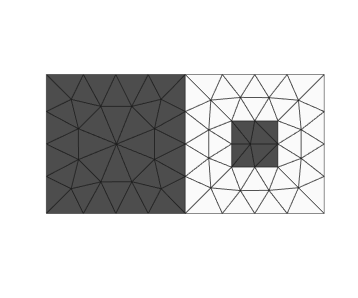

plotMeshes(vert,ele,tnum);

## Write inp file (opt.mode = 1)

The declaration of assembly and instance will be neglected. This is the concise format.

ele_type = 'CPS3';
precision = 8;
file_name = 'test_1.inp';
opt = [];
opt.mode = 1;

printInp2d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp2d Done! Check the inp file!


## Write inp file (opt.mode = 2)

Assembly and instance will be declared explicitly (normal mode). The exported inp file would have a model with one part, which contains multiple sections. Each section corresponds to one phase in the mesh.

ele_type = 'CPS3';
precision = 8;
file_name = 'test_2.inp';
opt = [];
opt.mode = 2;

printInp2d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp2d Done! Check the inp file!


## Write inp file (opt.mode = 3)

Assembly and instance will be declared explicitly (normal mode). The exported inp file would have a model with multiple parts, where each part corresponds to one phase in the mesh.

ele_type = 'CPS3';
precision = 8;
file_name = 'test_3.inp';
opt = [];
opt.mode = 3;

printInp2d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp2d Done! Check the inp file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo